clear
x = [-5:0.01:15];
y1 = sin(x);
y2 = 0.1*x;

j = 0;
for i = 1:1:2001
    if (abs(y1(1, i) - y2(1, i)) <= 0.004)
        j = j + 1;
        yroot (1, j) = y1(1, i);
        xroot (1, j) = -5 + i*0.01;
    end
end

xroot;
yroot;

figure
h1 = plot(x,y1,'r', "LineWidth",1) ;       
hold on
h2 = plot(x,y2,'k', "LineWidth",1) ;
h3 = plot(xroot, yroot, '.b','Marker','x', 'Linewidth', 1);

grid on     
axis([-5 15 -1.25 1.25])  
legend('$sin(x)$', '$0.1 \cdot x$','Interpreter','latex');
title ('$sin(x)$ and $0.1x$  functions','Interpreter','latex')
xlabel 'x' 
ylabel 'y'


X = ['Functions y = sin(x) and y = 0.1x intersect in 5 points from the domain of definition [-5; 15]:'];
disp(X)
for i = 1:1:5
    disp(['(' num2str(xroot(1, i)) ', ' num2str(yroot(1, i)) ');'])
    str = {'\leftarrow' num2str((xroot (1, i)), '%.2f') num2str((yroot (1, i)), '%.2f')};
    text(xroot(1, i)+0.1, yroot(1, i)-0.11, str)
end

clear
A = randi(7,1,20)+8;
B = zeros(1, 8);
for i = 1:1:(size(A, 2))
    k = 1;
    for j = i+1:1:(size(A, 2))
        if (A(1, i) == A(1, j))
            k = k+1;
        end
    end
   if (B(1, A(1, i)-7) == 0)
       B(1, A(1, i)-7) = k; % количество вхождений числа 
    end
end
B;
maxb = max(B);

h1 = histogram(A);
grid on
axis([7 16 0 maxb+1]) 
title ('histogram') 
h1.FaceColor = [0.1, 0.5, 0.3];
xlabel 'numbers from 8 to 15'
ylabel 'counts of the numbers'

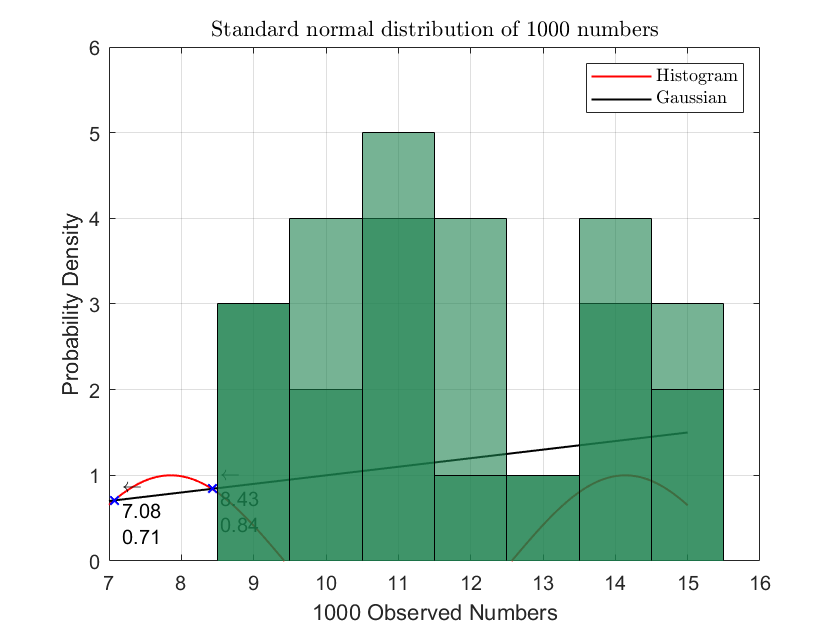

x = randn(1, 1000);
histogram(x,'Normalization','pdf') % probability density function
grid on
hold on
y = -5:0.1:5;
mu = 0; %normal distribution
sigma = 1;
f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi)); % density function
plot(y, f, '-.r', 'LineWidth', 1.5)

title ('Standard normal distribution of 1000 numbers') 
h.FaceColor = [rand rand rand];
xlabel '1000 Observed Numbers'
ylabel 'Probability Density'
legend('Histogram', 'Gaussian');

clear

A = load("table.txt");
X = A(2, :); % вторая строка
Y = A(4, :);
save('X.mat',"X")
save('Y.mat', "Y")

[xData, yData] = prepareCurveData( X, Y );

ft = fittype( 'a*x+b*x^2+c*x^3', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.919527571374986 0.754961961273751 0.437361874743673];

[fitresult, gof] = fit( xData, yData, ft, opts );

figure('Name', 'untitled fit 1' );

disp('Polynomial function parameters')
fitresult
h = plot( fitresult, xData, yData );
legend( h, 'data', 'fitted curve', 'Location', 'NorthWest');

xlabel( '$x$', 'Interpreter', 'latex');
ylabel( '$y$', 'Interpreter', 'latex');
grid on